% Load the CSV data
data_isec_orb = readtable('./isec_pose.csv');
data_isec_imu = readtable('./imu_data_compensated.csv');
timestamp_isec_orb = (data_isec_orb{:,1}-data_isec_orb{1,1});
timestamp_isec_imu = (data_isec_imu{:,1}-data_isec_imu{1,1});

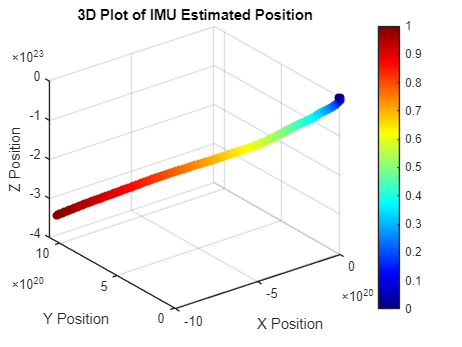

% --------------------- IMU Data ------------------- 
% TODO unfinished
orientation = data_isec_imu{:, 2:5};
gyro = data_isec_imu{:, 6:8};
accel = data_isec_imu{:, 9:11};

% Time differences
dt = diff(timestamp_isec_imu);

% Integrate acceleration to get velocity
velocity_x = cumtrapz(timestamp_isec_imu, accel(:, 1));
velocity_y = cumtrapz(timestamp_isec_imu, accel(:, 2));
velocity_z = cumtrapz(timestamp_isec_imu, accel(:, 3));

% Integrate velocity to get position
pos_x = cumtrapz(timestamp_isec_imu, velocity_x);
pos_y = cumtrapz(timestamp_isec_imu, velocity_y);
pos_z = cumtrapz(timestamp_isec_imu, velocity_z);

% Convert quaternion to Euler angles (yaw, pitch, roll)
euler_angles = quat2eul(orientation, 'XYZ');
yaw = euler_angles(:, 1);
pitch = euler_angles(:, 2);
roll = euler_angles(:, 3);

% Normalize timestamps for coloring 
timestamp_isec_imu_norm = (timestamp_isec_imu - min(timestamp_isec_imu)) / (max(timestamp_isec_imu) - min(timestamp_isec_imu));

% Plot the 3D trajectory
figure;
scatter3(pos_x, pos_y, pos_z, 36, timestamp_isec_imu_norm, 'filled');
colormap(jet);
colorbar;
grid on;
xlabel('X Position');
ylabel('Y Position');
zlabel('Z Position');
title('3D Plot of IMU Estimated Position');

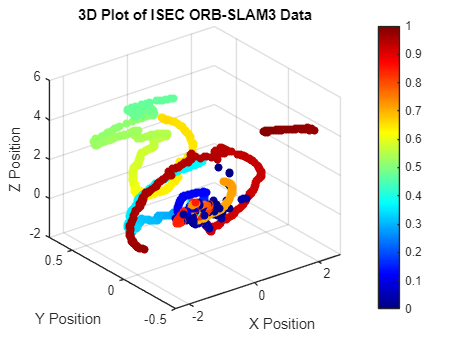

% --------------------- ORB-SLAM3 Pose Estimation Data ------------------- 
% Extract position columns 
x_pose = data_isec_orb.Var4; 
y_pose = data_isec_orb.Var5; 
z_pose = data_isec_orb.Var6; 

% Offset positions to start at (0,0,0) 
x_pose = x_pose - x_pose(1); 
y_pose = y_pose - y_pose(1); 
z_pose = z_pose - z_pose(1);

% Normalize timestamps for coloring 
timestamp_isec_orb_norm = (timestamp_isec_orb - min(timestamp_isec_orb)) / (max(timestamp_isec_orb) - min(timestamp_isec_orb));

% Plot the 3D trajectory 
figure; 
scatter3(x_pose, y_pose, z_pose, 36, timestamp_isec_orb_norm, 'filled'); 
colormap(jet); 
colorbar;
grid on;
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Plot of ISEC ORB-SLAM3 Data');